# Лабораторная работа №2 по СУвЭ

## Параметрический синтез и исследование цифровой системы управления с П-регулятором и объектом в виде последовательно включенных апериодического и интегрирующего звеньев из условия обеспечения заданного переходного процесса.

Определяем вариант задания:

ob.R = 0.1+unifrnd(-0.03,0.03);
ob.L = 0.02+unifrnd(-0.01,0.01);
ob.J = 100+unifrnd(-10,10);
ob.Ce = 2;
ob.Cm = ob.Ce;
save('data.mat', 'ob');

## Задание 1

Моделирование П-регулятора

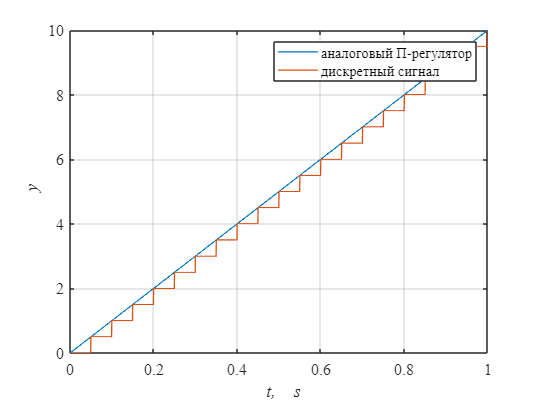

an.Kp = 10;%аналогавая система
dsc.Kp = 10;%дискретная система

Tmdl = 1;
To = 0.05;
warning off
simNew = sim('lab2_1.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.y(:,1);
an.y = simNew.y(:,2);
dsc.y = simNew.y(:,3);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,an.y,'Linewidth', 1)
hold on
grid on
plot(t,dsc.y,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it y')
legend('аналоговый П-регулятор', 'дискретный сигнал')

## **Задание 2**

### **Синтез системы с использованием «метода переоборудования»**

syms ia ua w e M
syms R L J Ce
syms dia dw
eq(1) = L*dia+ R*ia==ua-e;
eq(2) = J*dw==M;
eq(3) = e==Ce*w;
eq(4) = M==Ce*ia;

S1 = solve(eq,[dia dw e M]);
disp(collect(S1.dia, [ia w ua]))

$$\left(-\frac{R}{L}\right)\,\mathrm{ia}+\left(-\frac{\mathrm{Ce}}{L}\right)\,w+\frac{\mathrm{ua}}{L}$$

disp(collect(S1.dw, [ia w ua]))

$$\frac{\mathrm{Ce}}{J}\,\mathrm{ia}$$

A = [-R/L -Ce/L;
    Ce/J 0;];
B=[1/L; 0];
C = [1 0];
D = [0];

syms s
Wia = C*(s*eye(2) - A)^-1*B + D;
disp(collect(Wia, s))

$$\frac{J\,s}{\left(J\,L\right)\,s^{2}+\left(J\,R\right)\,s+{\mathrm{Ce}}^{2}}$$

Wia_spml = 1/(L*s+R);
disp(collect(Wia_spml, s))%пренебрегаем противоЭДС

$$\frac{1}{L\,s+R}$$

АЧХ и ФЧх разомкнутых систем

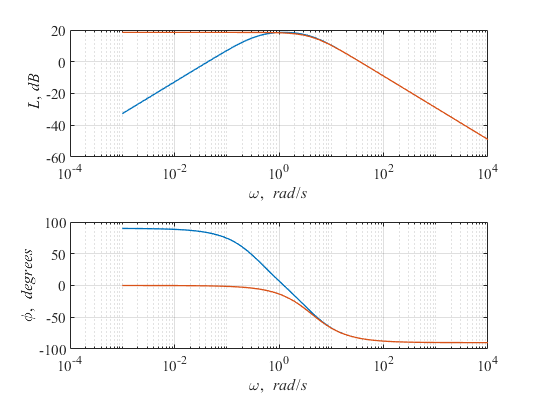

wfr = 10.^(-3:0.1:4);
sfr = 1i*wfr;
wia_tf = ob.J*sfr./(ob.J*ob.L*sfr.^2+ob.J*ob.R*sfr+ob.Ce^2);
wia_sm = 1./(ob.L*sfr+ob.R);

Lw_tf = 20*log10(abs(wia_tf));
phi_tf = angle(wia_tf)*180/pi;

Lw_sm = 20*log10(abs(wia_sm));
phi_sm = angle(wia_sm)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(wfr ,Lw_tf,'Linewidth', 1)
hold on
grid on
plot(wfr ,Lw_sm,'Linewidth', 1)
set(ax(1), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\it L\rm, \itdB')

ax(2) = subplot(2,1,2);
plot(wfr ,phi_tf,'Linewidth', 1)
hold on
grid on
plot(wfr ,phi_sm,'Linewidth', 1)
set(ax(2), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\phi, \it degrees')

linkaxes(ax, 'x')

#### Расчет ПИ регулятора тока

syms Tt s
wol = 1/(Tt*s)

$$wol = \frac{1}{\mathrm{Tt}\,s}$$

wreg = wol/Wia_spml;
disp(collect(wreg, s))

$$\frac{L\,s+R}{\mathrm{Tt}\,s}$$

### Когда и почему можем пренебрегать противоЭДС 

АЧХ и ФЧХ замкнутой системы

Tt = 10 %при 0.5 система статическая, при увеличении Tt сильнее отличаются ФЧХ и АЧХ реальной и пренебрегаемой систем

Tt = 10

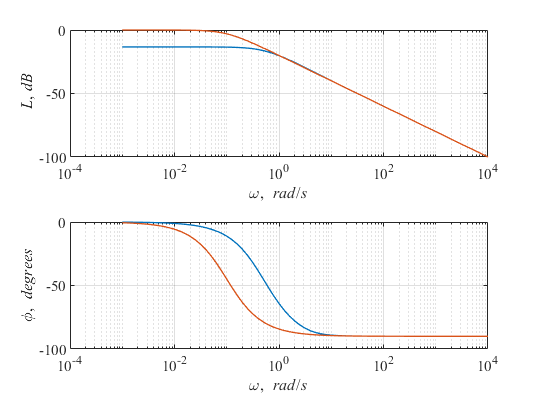

wfr = 10.^(-3:0.1:4);
sfr = 1i*wfr;
wia_tf = ob.J*sfr./(ob.J*ob.L*sfr.^2+ob.J*ob.R*sfr+ob.Ce^2);
wia_sm = 1./(ob.L*sfr+ob.R);
wreg_tf = (ob.L*sfr+ob.R)./(Tt*sfr);

wreal = wreg_tf.*wia_tf./(1+wreg_tf.*wia_tf);
wet = wreg_tf.*wia_sm./(1+wreg_tf.*wia_sm);

Lw_tf = 20*log10(abs(wreal));
phi_tf = angle(wreal)*180/pi;

Lw_sm = 20*log10(abs(wet));
phi_sm = angle(wet)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(wfr ,Lw_tf,'Linewidth', 1)
hold on
grid on
plot(wfr ,Lw_sm,'Linewidth', 1)
set(ax(1), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\it L\rm, \itdB')

ax(2) = subplot(2,1,2);
plot(wfr ,phi_tf,'Linewidth', 1)
hold on
grid on
plot(wfr ,phi_sm,'Linewidth', 1)
set(ax(2), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\phi, \it degrees')

linkaxes(ax, 'x')

#### Моделирование работы контура тока

Tt = 0.001;
crl.Kpa = ob.L/Tt;
crl.Kia = ob.R/Tt;

Tmdl = 0.01;
To = 0.05;
warning off
simNew = sim('lab2_2my', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab2_2my/Subsystem/Current Regulator/Gain
lab2_2my/Subsystem/Current Regulator/Sum
lab2_2my/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_2my/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_2my/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE


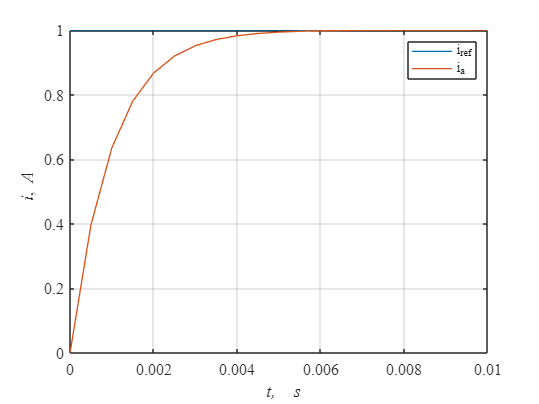

warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
isens = simNew.ia(:,3);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,isens,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i\rm, \itA')
legend('i_{ref}', 'i_a')

#### Расчет цифрового П-регулятора скорости

syms Tu Tt s

коэффициент датчика скорости

syms kdw
Wcrl = 1/(Tt*s+1);
Wob2 = Ce*kdw/(J*s)

$$Wob2 = \frac{\mathrm{Ce}\,\mathrm{kdw}}{J\,s}$$

передаточная функция раз. системы, настроенный на техн. оптиум

Tu=Tt;
wol = 1/(2*Tu*s*(Tu*s+1));
Wreg = wol/(Wcrl*Wob2);
disp(collect(Wreg, s))

$$\frac{J}{2\,\mathrm{Ce}\,\mathrm{Tt}\,\mathrm{kdw}}$$

#### Моделирование работы системы, настроенной на тех. оптиум

Tt = 0.005;
To=0.001;
crl.Kpa = ob.L/Tt;
crl.Kia = ob.R/Tt;
kdw = 180/pi;
Tmdl = 0.1;

stl.Kpa = ob.J*kdw/2/ob.Ce/Tt;
stl.Kpd = stl.Kpa;

warning off
simNew = sim('lab2_2bmy.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab2_2bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_2bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_2bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_2bmy/Subsystem/Current Regulator/Sum1
lab2_2bmy/Subsystem/Current Regulator/Gain


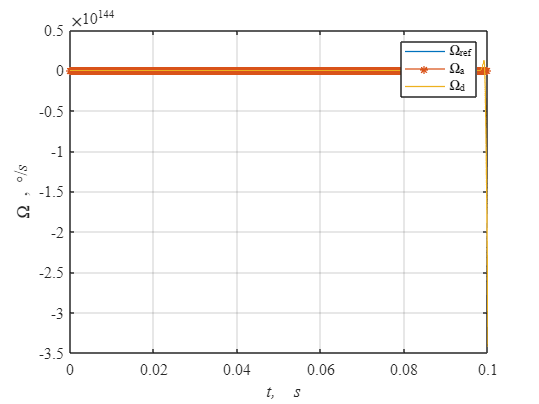

warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1, 'Marker', '*')
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d')